First list the sessions in the database.

warning('off')
T = make_sessions_table

T = 35×18 table
     sess_date      rat        sessid                                                                                    mat_file_name                                                                                  probe_serial     days_implanted    n_clusters    craniotomy_AP    craniotomy_ML    depth_inserted    hemisphere    region_names    n_trials    violation_rate    percent_correct    laser_power_mW    D2Phototagging                                                             session_notes                                                         
    ___________    ______    __________    ________________

Load one of them (the last one, just for examples).

Cells = load(T.mat_file_name{end})

Cells = struct with fields:
                   rec: [1×1 struct]
              jrc_file: 'E:\Adrian\A256\A256_2020_09_28\A256_2020_09_28_g0\spikesort_2020_11_23_09_09_42_ks2jrc\A256_2020_09_28_g0_t0.imec0.ap.artifact_removed_res.mat'
         mat_file_name: 'E:\Adrian\A256\A256_2020_09_28\A256_2020_09_28_g0\spikesort_2020_11_23_09_09_42_ks2jrc\A256_2020_09_28_g0_t0.imec0.ap.artifact_removed_res.Cells.mat'
               made_by: 'make_Cells_from_JRC'
                params: 'time_s_from_last_ts_to_include_spike'
                Trials: [1×1 struct]
               nTrials: 479
                sessid: 787674
         last_modified: 25-Nov-2020 14:47:22
                   rat: 'A256'
             sess_date: '2020-09-28'
                  bank: [368×1 double]
             electrode: [368×1 double]
             unitCount: [368×1 double]
          unitISIRatio: [1×368 double]
            unitLRatio: [1×368 double]
           unitIsoDist: [1×368 double]
            unitVppRaw: [368×1 single]


Use the new utility function "calculate_unit_stability" to get the stability metric and number of spikes per trial for each cell. The stability metric is the ratio of sd's of two distributions of trial-averaged firing rates A and B. A is the distribution obtained by repeatedly sampling groups of contiguous trials. B is the distribution obtained by repeatedly sampling random groups of trials. If the ratio is large, it means sampling groups of trials that are contiguous in time gives a broader distribution of rates than you'd expect -- i.e. the variability in firing rate across time is systematic. For a neuron whose firing rate statistics do not change across the session, the stability metric would be exactly 1.

[stability,presence,nspks] = calculate_unit_stability(Cells)

stability =     8.7693    2.5784    4.2533    4.0718    3.2662    1.8006    1.6544    2.4046    1.6713    0.7985    1.6770    1.3151    4.4293    1.6132    1.0655    0.9449    5.3636    0.9959    3.6196    6.7443    0.6686    1.8796    3.0314    2.6084    1.2485    1.9284    0.9674    4.4240    1.6552    0.8835    1.4096    1.4346    1.8367    2.9743    1.7280    4.9144    1.5848    1.4071    1.5219    0.9077    1.0934    0.7678    1.4466    1.2888    2.5146    0.8712    2.5496    2.8206    2.4867    3.5054


presence =     0.9875    0.1065    0.9958    1.0000    1.0000    0.8706    0.1795    0.5699    0.6618    0.0960    0.4092    0.0856    0.9290    0.4530    0.2463    0.9165    0.8935    0.0960    0.3486    0.9937    0.1524    0.2777    0.8894    1.0000    0.4572    0.7933    0.0125    1.0000    0.9896    0.8789    1.0000    0.2192    0.8413    0.6263    0.2923    1.0000    0.2443    0.9332    0.1336    0.4906    0.5240    0.1002    0.2505    0.8914    1.0000    0.2463    1.0000    0.3236    0.6534    0.8372


nspks =    13.1127    0.2067    9.4593   77.3779   33.7244   10.4280    0.3925    2.2296    2.5177    0.1608    1.5491    0.1441    8.3904    2.3716    0.3967    3.1503    5.4113    0.1148    1.0042   12.6576    0.1858    0.7307    5.8977   92.5052    0.8914    2.1628    0.0125   75.4614   21.6284    4.3236   17.3570    0.4843    3.3382    1.5532    0.4885   25.8768    0.3737    4.8706    0.1670    1.0668    1.6952    0.2276    0.3090    4.2234   11.7035    0.2985    9.1148    0.6848    3.8873    5.0898


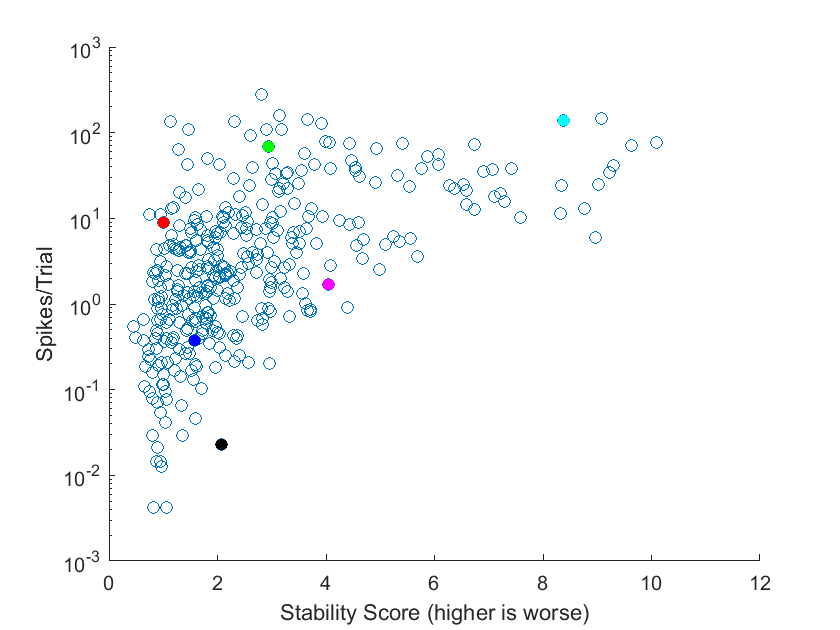

cla;scatter(stability,nspks);hold on
examples = [156 267 234 246 361 37];
colors ={'r','g','c','m','k','b'};
for i=1:6
    scatter(stability(examples(i)),nspks(examples(i)),colors{i},'filled');hold on;
end
xlabel('Stability Score (higher is worse)')
ylabel('Spikes/Trial')
set(gca,'yscale','log')

What you can see is that the majority of cells form a cluster with stability slightly above 1 (i.e. some excess variability across time but not much). Then there is a long tail of cells with stability values much greater than 1. Cells with very low firing rates do not show large stability scores because Poisson variability (which shows up in both the A and B distribution) swamps variability across time. You probably want to exclude these cells anyway.

To get a sense of what the firing rate of cells in the above distribution look like, I've flagged 6 example cells. I've plotted spikes/trial across the session for each cell. A threshold of about 4 or 5 for the stability score seems reasonable to exclude cells which are truly anomalously unstable. This would exclude 10-15% of cells for this session.

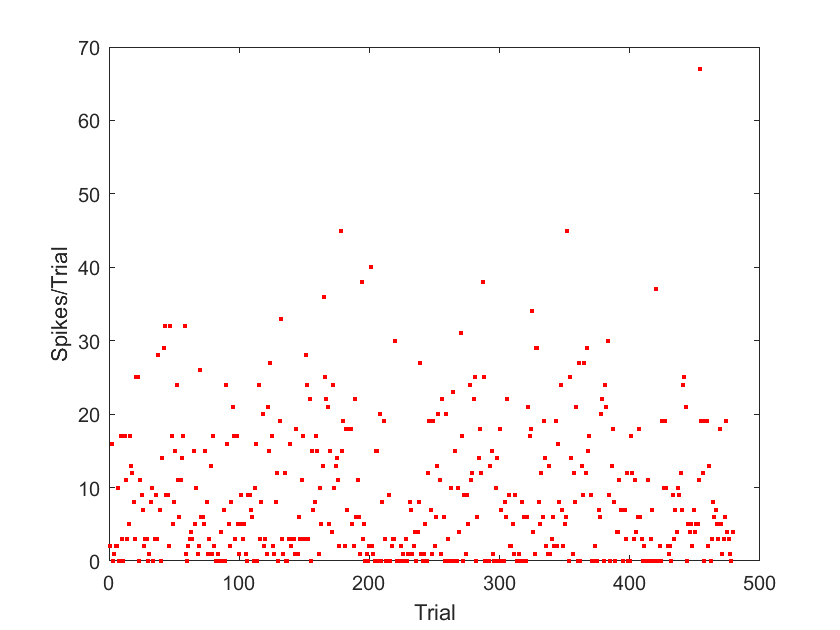

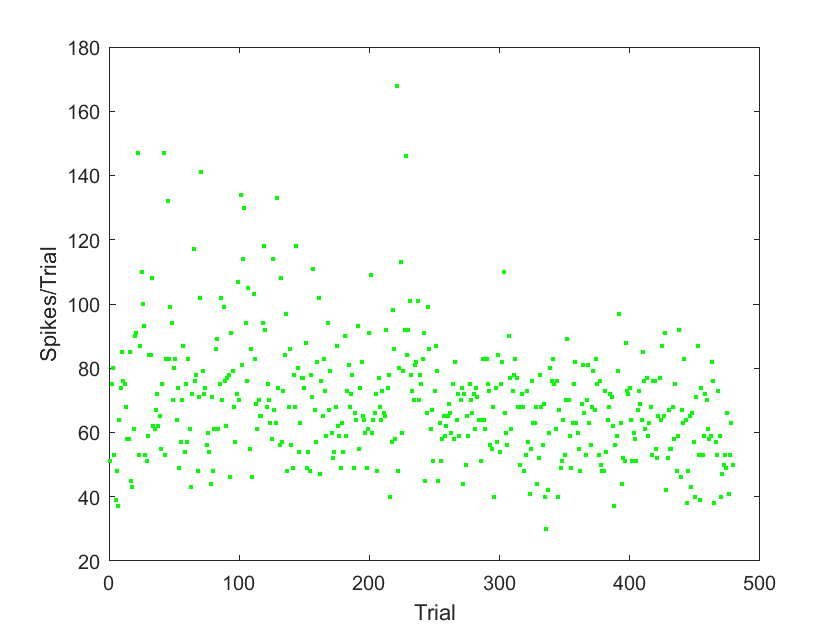

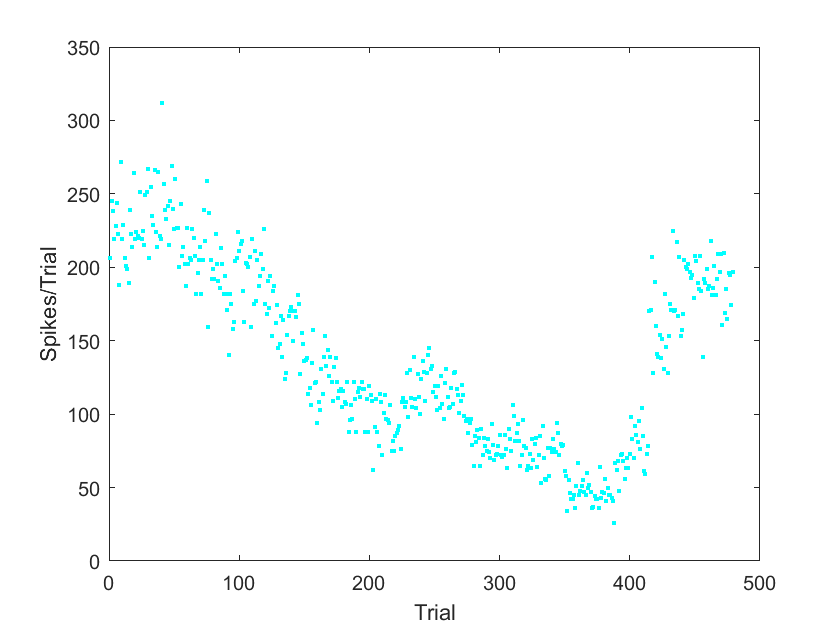

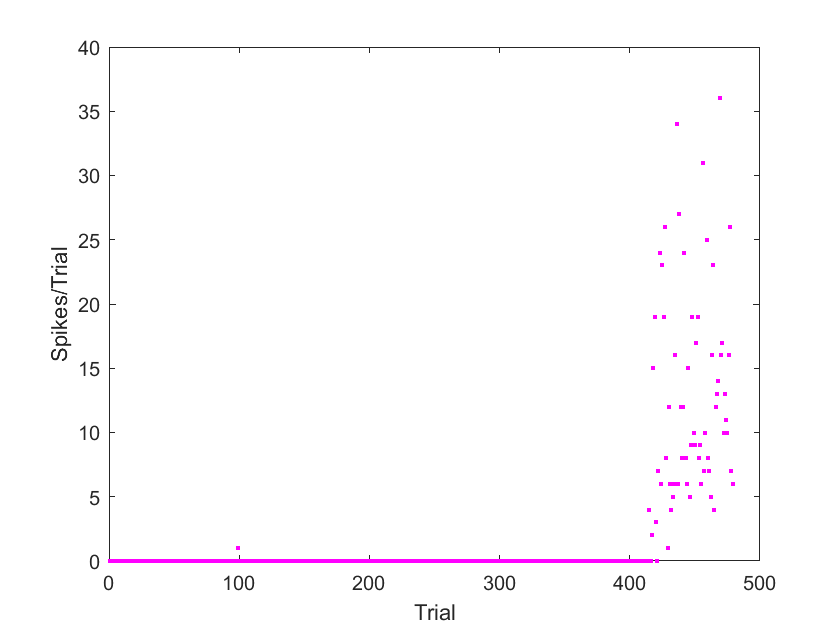

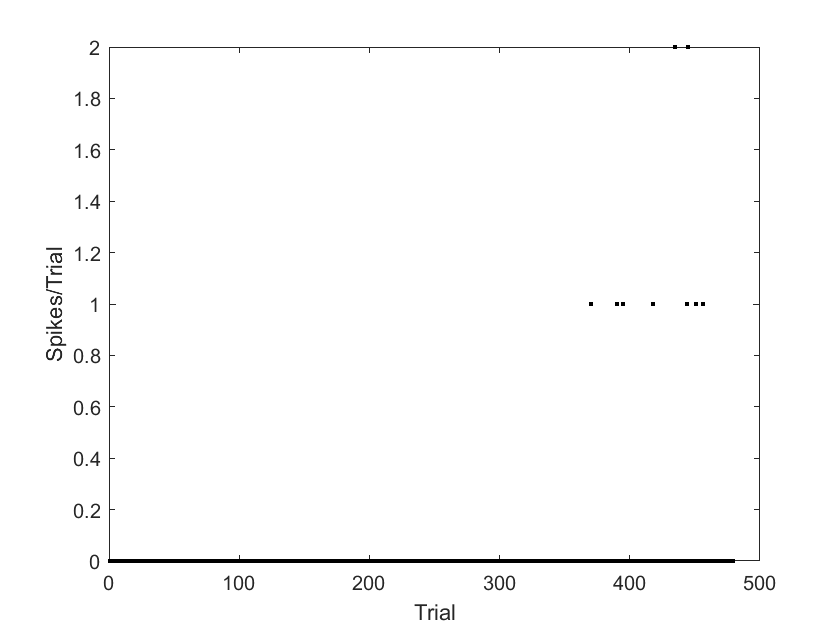

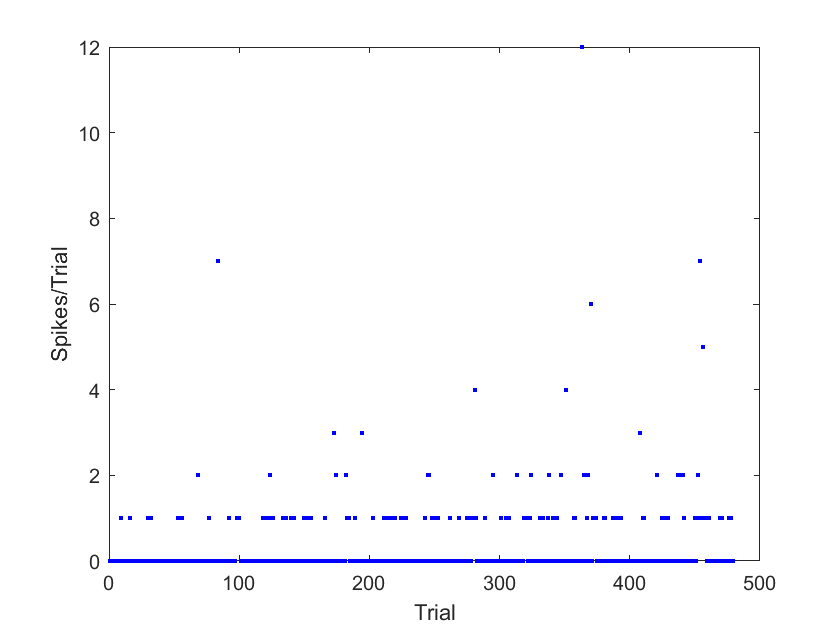

for i=1:6
    figure;plot(cellfun(@numel,Cells.spike_time_s.cpoke_in{examples(i)}),sprintf('.%s',colors{i}));xlabel('Trial');ylabel('Spikes/Trial')
end

The function "calculate_unit_stability" also returns a value called "presence." This is the fraction of trials for which a unit spiked. Excluding cells for which that value is less than 0.5 (i.e. fired on less than half of trials) seems also reasonable and excludes the low firing rate cells (about 1/3 of cells).

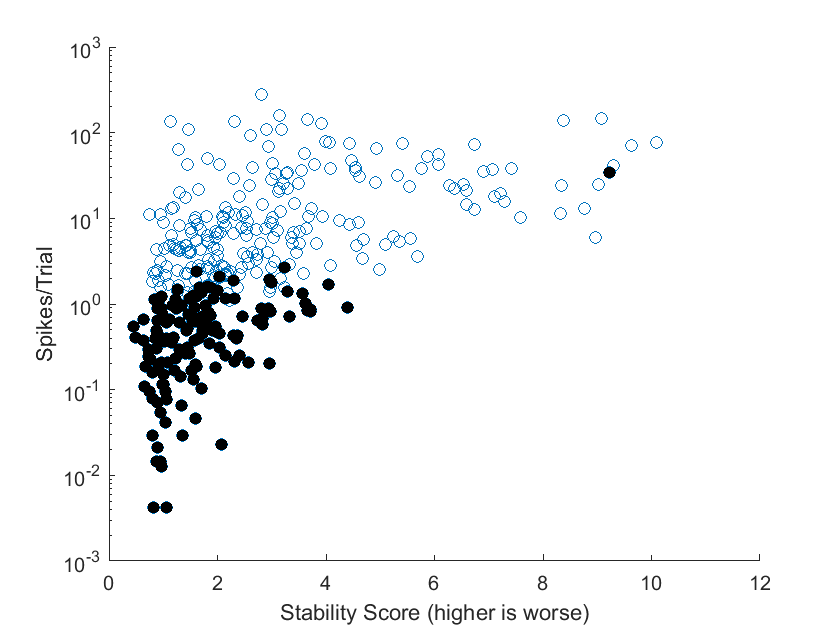

figure
scatter(stability,nspks)
hold on
scatter(stability(presence<0.5),nspks(presence<0.5),'k','filled')
set(gca,'yscale','log')
xlabel('Stability Score (higher is worse)')
ylabel('Spikes/Trial')